# SISTEMAS DE CONTROL II

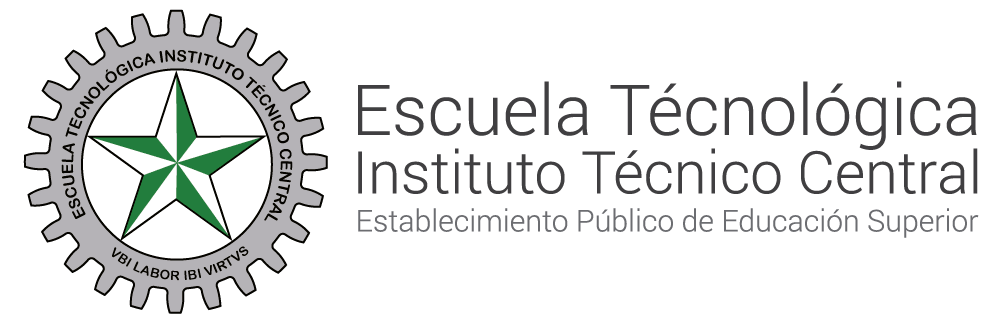

# TRASFORMADA Z

**Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c**

**Coautores:  Henry Daniel Mora lozano, Miguel Johany Guayara Gutierrez**

**¿QUE ES LA TRASFORMADA Z ?**

La **transformada Z** es una herramienta matemática utilizada en el análisis y el diseño de sistemas discretos, especialmente en el ámbito de las señales y sistemas digitales. Es una extensión de la transformada de Laplace, pero para señales y sistemas que operan en tiempos discretos.

La transformada Z de una secuencia discreta $f\left\lbrack k\right\rbrack$ , donde k es un índice entero, se define como:


$$F\left(z\right)=\sum_{k=-\infty }^{\infty } f\left\lbrack k\right\rbrack z^{-k}$$


Donde:

- $F\left(z\right)$ es la transformada Z de la secuencia $f\left\lbrack k\right\rbrack$

- k es el índice de la secuencia discreta.

La transformada Z convierte la secuencia en una función de la variable compleja $z$ , lo que permite analizar la respuesta del sistema en el dominio de $z$.

#### ¿Como obtener la trasformada z?

Vamos a tomar como ejemplo la siguiente funcion :


$$k^2$$

$$T^2$$


Generamos un codigo para mostrar nuestra Transformada Z de la funcion $k^2 \ldotp T^2$ tomamos un rango de 0 a 1 muestras y definimos T=1

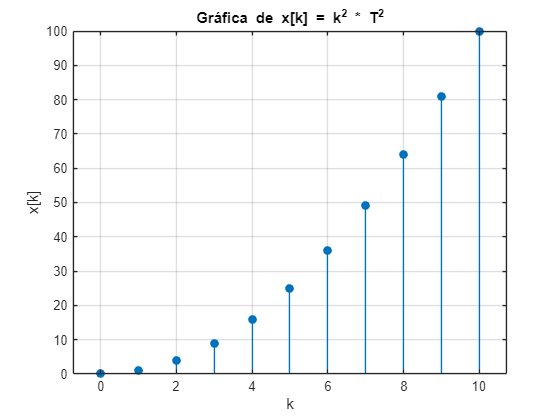

T = 1; 
k = 0:10;  
x = (k.^2) * T^2;
syms z;  
X_z = 0;  
for n = 1:length(k)
    X_z = X_z + x(n) * z^(-(n-1)); 
end
figure;
stem(k, x, 'filled');
xlabel('k');
ylabel('x[k]');
title('Gráfica de x[k] = k^2 * T^2');
grid on;

podemos empezar porque la funcion $k^2$$T^2$ =>  x[k]

aplicamos la definicion de la trasformada z

 
$$F\left(z\right)=\sum_{k=-\infty }^{\infty } f\left\lbrack k\right\rbrack z^{-k}$$
 

remplazamos ya que en este caso $f\left\lbrack k\right\rbrack$= x[k] => $k^2$$T^2$

$x\left(z\right)=\sum_{k=0}^{\infty } \left\lbrack k^2 \ldotp T^2 \right\rbrack z^{-k}$ => $X\left(z\right)=T^2 \sum_{k=0}^{\infty } \left\lbrack k^2 \right\rbrack z^{-k}$ (se saca $T^2$ al ser constante y unicamente operamos la sumatoria en $k^2$) 

Partimos de la transformada z del escalon unitario, para llevarla a la transformada z de $k^2$.

$\sum_{k=0}^{\infty } z^{-k}$=1+$z^{-1} +z^{-2} +\ldotp \ldotp \ldotp z^{-\infty }$

esta serie es = $\frac{z}{z-1}$ para [z]>1 por lo tanto esto es = $\sum_{k=0}^{\infty } z^{-k}$= $\frac{z}{z-1}$

realizamos la primera derivada de la funcion $\sum_{k=0}^{\infty } z^{-k}$ esto con el objetivo de llegar al exponente deseado de la variable (k) en la funcion $k^2$

$\frac{d}{\textrm{dz}}$[$\sum_{k=0}^{\infty } \left.z^{-k} \right\rbrack$=$\sum_{k=0}^{\infty } \left(-k\right)z^{-k-1}$    al derivar $z^{-k}$ baja $-k$ a multiplicar  z y restamos -1 en el exponente.

como derivamos de un lado, se debe derivar tambien del otro, entonces realizamos la derivada de la siguente transformada:

 
$$\frac{z}{z-1}$$
   

$\frac{d}{\textrm{dz}}\left\lbrack \frac{z}{z-1}\right\rbrack =\frac{z-1-z}{{\left(z-1\right)}^2 }=\frac{-1}{{\left(z-1\right)}^2 }$ simplificamos en el numerador, ya que tenenemos $z^1 {-z}^1$, quedandonos -1 en el numerador.

obteniendo la siguente funcion producto de la derivacion de las dos funciones anteriores

$\sum_{k=0}^{\infty } \left(-k\right)z^{-k-1}$=$\frac{-1}{{\left(z-1\right)}^2 }$ multiplicamos por -z obteniendo $\sum_{k=0}^{\infty } \left\lbrack {\textrm{kz}}^{-k} \right\rbrack =\frac{z}{{\left(z-1\right)}^2 }$

esto se logra ya que el -z a ambos lados de la igualdad nos vuelve positiva  la variable k, y adicional, como le multiplicamos el z que lleva como exponente 1, restamos del exponente el -1, quedandonos ${\textrm{kz}}^{-k}$, a la derecha de la ecuacion nos queda z positivo en el numerador. 

procedemos a derivar nuevamente la primer funcion obtenida $\sum_{k=0}^{\infty } \left\lbrack {\textrm{kz}}^{-k} \right\rbrack$

$\frac{d}{\textrm{dz}}\left\lbrack \sum_{k=0}^{\infty } \left\lbrack {\textrm{kz}}^{-k} \right\rbrack \right\rbrack$=$\sum_{k=0}^{\infty } \left({-k}^2 \right)z^{-k-1}$ la segunda derivada nos lleva la variable k a su exponente de interes, en este caso ${-k}^2$, que posteriormente debe quedarnos positiva.

derivamos por segunda vez la transformada z obtenida $\frac{z}{{\left(z-1\right)}^2 }$


$$\frac{d}{\textrm{dz}\;}\left\lbrack \frac{z}{{\left(z-1\right)}^2 }\right\rbrack =\left(\frac{{\left(z-1\right)}^2 -2z\left(z-1\right)}{{\left(z-1\right)}^4 }\right)$$


resolvemos lo que esta entre los parentesis obteniendo 

$\frac{z^2 -2z+1-2z^2 +2z}{{\left(z-1\right)}^4 }=$ $\frac{z^2 -2z^2 +1}{{\left(z-1\right)}^4 }$ ya que restamos ${2z}^1$${-2z}^1$=0 , continuamos simplificando y nos da  $\frac{-z^2 +1}{{\left(z-1\right)}^4 }$ por operar 

$z^2 -2z^2$= $-z^2$ 

continuamos factorizando el negativo del numerador

$\frac{-z^2 +1}{{\left(z-1\right)}^4 }=\frac{-\left(z^2 -1\right)}{{\left(z-1\right)}^4 }$  y tambien factorizamos $\left(z^2 -1\right)$ que nos queda $\left(z-1\right)$$\left(z+1\right)$

$\frac{-\left(z-1\right)\left(z+1\right)}{{\left(z-1\right)}^4 }$ podemos cancelar $\left(z-1\right)$en el numerador con un $\left(z-1\right)$ del denominador  quedandonos ${\left(z-1\right)}^3$

 como resultado obtenemos  $\frac{-\left(z+1\right)}{{\left(z-1\right)}^3 }$

la transformada obtenida la multiplicamos por -z

$\sum_{k=0}^{\infty } -K^2 z^{-k-1} =\frac{-\left(z+1\right)}{{\left(z-1\right)}^3 }$ al igual que en la primera derivada, al multiplicar por -z logramos tener $K^2$ por el negativo de la z, y la z multiplicando a la z que tiene como exponente 1, operamos el -1 del exponente  dandonos como resultado $K^2 z^{-k}$.

y al lado derecho en la transformada Z $\;\textrm{multiplicarlo}\;\textrm{por}-z\;\;\textrm{en}\;\textrm{el}\;\textrm{numerador}-\left(z+1\right)$ nos da como resultado $z\left(z+1\right)$

la sumatoria nos quedaria:


$$\sum_{k=0}^{\infty } K^2 z^{-k} =\frac{z\left(z+1\right)}{{\left(z-1\right)}^3 }$$
 

despues de operar procedemos a agregar a nuestra nueva ecuacion la constante  $T^2$, la cual sacamos de la sumatoria al inicio

pero debe ponerse a ambos lados de la ecuacion

obtenemos : x(z)=$T^2$$\sum_{k=0}^{\infty } K^2 z^{-k}$   =     $\frac{T^2 \ldotp Z\left(Z+1\right)}{{\left(Z-1\right)}^3 }$ 

por lo tanto podemos decir que la trasformada Z de $k^2 \ldotp T^2 \;$es:


$$x\left(z\right)=\frac{T^2 \ldotp Z\left(Z+1\right)}{{\left(Z-1\right)}^3 }$$


comprobamos directamente definiendo A como $k^2 \;$ y B como $T^2$ luego para la funcion f(k)= $k^2 \ldotp T^2$ es decir A*B

y para calcular la transformada z definimos F con la funcion de Matlab ztrans(f,k) para mostrar el resultado de la transformada z

syms f(k) a T
A=k^2;
B=T^2;
f(k) = A*B;
F = ztrans(f,z)

$$F = \frac{T^{2}\,z\,\left(z+1\right)}{{\left(z-1\right)}^{3}}$$